PARA LEER LAS VARIABLES AyB:

% Inicializar las variables para los coeficientes
b_str = strings(size(ba, 1), 1);  % Coeficientes del numerador (b)
a_str = strings(size(ba, 1), 1);  % Coeficientes del denominador (a)

% Paso 2: Concatenar los coeficientes de las filas
for i = 1:size(ba, 1)
    % Extraer los fragmentos de la tercera dimensión y concatenarlos
    b_str(i) = strjoin(cellstr(squeeze(ba(i, 1, :))'), '');  % Coeficiente b
    a_str(i) = strjoin(cellstr(squeeze(ba(i, 2, :))'), '');  % Coeficiente a
end

% Paso 3: Convertir las cadenas a números
b = str2double(b_str);  % Convertir las cadenas de coeficientes 'b' a números
a = str2double(a_str);  % Convertir las cadenas de coeficientes 'a' a números

%SI ES FIR:
%a=1;

% Paso 4: Verificar que no haya errores en la conversión
if any(isnan(b)) || any(isnan(a))
    error('Hay un error en la conversión de coeficientes. Revisa los datos originales.');
end

% Mostrar los coeficientes
disp('Coeficientes b:');

Coeficientes b:


disp(b);

   1.0e-03 *

    0.0051
         0
   -0.0406
    0.0000
    0.1419
    0.0000
   -0.2839
    0.0000
    0.3549
    0.0000
   -0.2839
    0.0000
    0.1419
   -0.0000
   -0.0406
         0
    0.0051




disp('Coeficientes a:');

Coeficientes a:


disp(a);

   1.0e+03 *

    0.0010
   -0.0136
    0.0874
   -0.3545
    1.0150
   -2.1753
    3.6098
   -4.7325
    4.9541
   -4.1549
    2.7827
   -1.4727
    0.6037
   -0.1853
    0.0402
   -0.0055
    0.0004



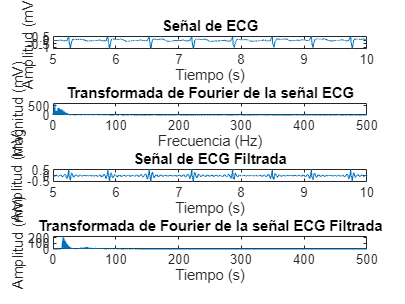

% Código para leer la señal ECG de un archivo OpenSignals
% Configuración del archivo
filename = '3D_respiracion.txt'; %  'archivo.txt'

% Abrir el archivo
fid = fopen(filename, 'r');

% Leer el encabezado JSON y eliminarlo
line = fgetl(fid); 
while ~contains(line, 'EndOfHeader')
    line = fgetl(fid); % Avanza línea por línea hasta llegar al final del encabezado
end

% Leer los datos numéricos
data = fscanf(fid, '%f', [6, Inf]); % Lee los datos en un formato de 6 columnas (de acuerdo al formato presentado)
data = data'; % Transponer la matriz para tener las filas como instancias de tiempo

% Cerrar el archivo
fclose(fid);

% Extraer la señal de ECG de la columna "A2" (última columna)
ECG_signal = data(:, 6); % "A2" corresponde a la sexta columna del archivo
n=10;   %Numero de bits
VCC=3.3; %Alimentación 
volts = (((ECG_signal/(2^n))-(1/2)) * VCC)/1009;
ECG_signal=volts*1000;      %señal en milivoltios
% Parámetros
fs = 1000; % Frecuencia de muestreo en Hz (según el encabezado)

% Gráfica de la señal ECG
t = (0:length(ECG_signal)-1)/fs; % Crear vector de tiempo basado en la longitud de la señal y la frecuencia de muestreo


% Eliminar el componente DC restando la media
ECG_noDC = ECG_signal - mean(ECG_signal);

%% Sección de FFT
N = length(ECG_noDC); % Número de muestras
f = (0:N-1)*(fs/N); % Vector de frecuencias
ECG_fft = fft(ECG_noDC); % FFT de la señal filtrada
% Tomar solo la mitad positiva del espectro, utilizando el valor entero de N/2
f_half = f(1:floor(N/2)); % Frecuencias positivas
ECG_fft_magnitude = abs(ECG_fft(1:floor(N/2))); % Magnitud de la FFT (solo mitad positiva)
ECG_filtered = filtfilt(b, a, ECG_signal); % Aplicar filtro

%% Sección de FFT
N = length(ECG_filtered); % Número de muestras
f = (0:N-1)*(fs/N); % Vector de frecuencias
ECG_fft_filtered = fft(ECG_filtered); % FFT de la señal filtrada
% Tomar solo la mitad positiva del espectro, utilizando el valor entero de N/2
f_half_filtered = f(1:floor(N/2)); % Frecuencias positivas
ECG_fft_magnitude_filtered = abs(ECG_fft_filtered(1:floor(N/2))); % Magnitud de la FFT (solo mitad positiva)


figure;
subplot(411);
plot(t, ECG_signal);
title('Señal de ECG');xlabel('Tiempo (s)');ylabel('Amplitud (mV)');
xlim([5,10])

% Graficar la FFT
subplot(412);
plot(f_half, ECG_fft_magnitude);
title('Transformada de Fourier de la señal ECG');xlabel('Frecuencia (Hz)');ylabel('Magnitud (mV)');

% Graficar la señal filtrada
subplot(413);
plot(t, ECG_filtered);
title('Señal de ECG Filtrada');xlabel('Tiempo (s)');ylabel('Amplitud (mV)');
xlim([5,10])

% Graficar la FFT filtrada
subplot(414);
plot(f_half_filtered, ECG_fft_magnitude_filtered);
title('Transformada de Fourier de la señal ECG Filtrada' );xlabel('Tiempo (s)');ylabel('Amplitud (mV)');